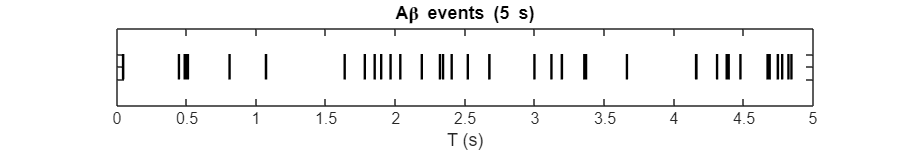

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% This code can be used to reproduce the time series of PVIN and PKCgIN
% in the simulated neural circuit shown in Fig. 7 in the manuscript in preparation:
% "Ma, X., Miraucourt, L., Qiu, H., Sharif-Naeini, R., Khadra, A. (2023). 
% Calcium buffering tunes intrinsic excitability of spinal dorsal horn 
% parvalbumin-expressing interneurons: A computational model."
%
%---------------------------------------------
% Tested Under MATLAB Version: 9.12.0 (R2022a)
% Time-stamp: <2023-Jan-17> 
%---------------------------------------------
%
% Xinyue Ma
% Email: xinyue.ma@mail.mcgill.ca
% Integrated Program in Neuroscience
% McGill University
% Montreal, QC, H3A 1A1 
% Canada
%
%-------------------------------------------
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Abeta fiber
% -----------------------------
% Parameter
% -----------------------------
abeta_fre = 5; dt_stim = 0.0002; TSyn = 5; rng(3); 
fpos = [0,0,600,100];
dt = 0.01; % for model integration
global gAMPA gNMDA gGABA gGlycin tStim
tStim = 0:dt_stim:TSyn; nTrials = 1;

% -- synapse time constant (msec)
rtau_ampa = 0.1; dtau_ampa = 5;
rtau_nmda = 2; dtau_nmda = 100; 
rtau_gaba = 0.1; dtau_gaba= 20;
rtau_glycin = 0.1; dtau_glycin= 10;

% -- independent Poisson distributed synaptic input
ifspike = poissonSpikeGen ( abeta_fre , tStim , nTrials );
tdelay = tStim(ifspike); 

% visualize temporal Abeta fiber events in raster plot
f_AbEvent = figure('Position', fpos);
plot( [tdelay; tdelay],...
      [zeros(1,length(tdelay)); ones(1,length(tdelay))],'LineWidth',1.2,"Color",'k'); 
xlabel('T (s)'); title(['A\beta events (',num2str(TSyn),' s)']); yticklabels(''); ylim([-1,2]); xlim([0 TSyn])

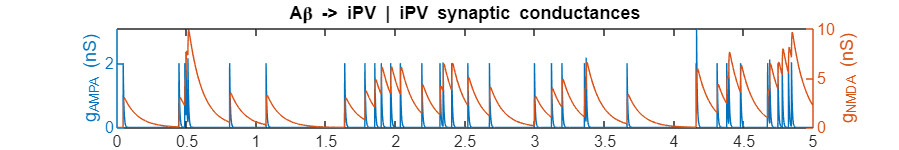

% -- Abeta Output to iPV
w_ampa_ab_pv = 2; w_nmda_ab_pv = 3; 
gAMPA_ab_pv = genSyn(tStim, tdelay, w_ampa_ab_pv, rtau_ampa, dtau_ampa);
gNMDA_ab_pv = genSyn(tStim, tdelay, w_nmda_ab_pv, rtau_nmda, dtau_nmda);

f_ab_iPV_syn = figure('Position',fpos);
yyaxis left;  plot(tStim, gAMPA_ab_pv); ylabel('g_{AMPA} (nS)')
yyaxis right; plot(tStim, gNMDA_ab_pv); ylabel('g_{NMDA} (nS)')
xlim([0,5]); title('A\beta -> iPV | iPV synaptic conductances')

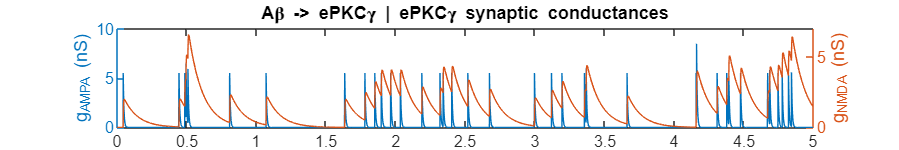


% -- Abeta Output to ePKCgamma
w_ampa_ab_pkc = 5.5; w_nmda_ab_pkc = 2; 
gAMPA_ab_pkc = genSyn(tStim, tdelay, w_ampa_ab_pkc, rtau_ampa, dtau_ampa);
gNMDA_ab_pkc = genSyn(tStim, tdelay, w_nmda_ab_pkc, rtau_nmda, dtau_nmda);

f_ab_ePKC_syn = figure('Position', fpos);
yyaxis left;  plot(tStim, gAMPA_ab_pkc); ylabel('g_{AMPA} (nS)')
yyaxis right; plot(tStim, gNMDA_ab_pkc); ylabel('g_{NMDA} (nS)')
xlim([0,5]); title('A\beta -> ePKC\gamma | ePKC\gamma synaptic conductances')

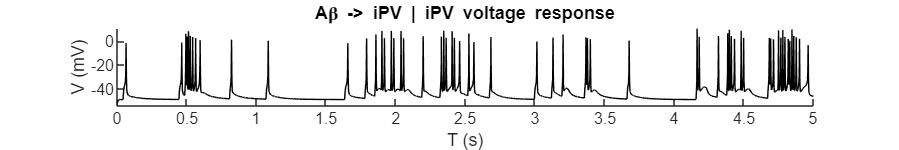

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% iPV response to Abeta fiber
% -----------------------------
% Parameter
% -----------------------------
trest1 = 0; ttest = TSyn*1000; trest2 = 0;
% global t_model
t_model = 0:dt:(trest1+trest2+ttest);
gAMPA = gAMPA_ab_pv; 
gNMDA = gNMDA_ab_pv;

Bt = 90; Iapp = 200; r = [Bt, Iapp]; 
v_PV = []; gSyn = []; rtest = r(end);
y0 = [-53.8257152400347,0.953972187424341,0.298040237815853,0.00355125770355378,0.0701687665813503];

% - test stimuli
r(end) = rtest; 
opts = odeset('RelTol',1e-4,'AbsTol',1e-5); 
sol = ode45(@(t,y)PVIN_HH(t,y,r,'syn'), 0:dt:ttest, y0, opts);
y0 = sol.y(:,end);
v_PV = [v_PV(1:end), interp1(sol.x, sol.y(1,:), 0:dt:ttest, 'nearest')];

f_ipv_v = figure('Position', fpos);
plot(t_model/1000, v_PV, 'Color', 'k'); box off
xlabel('T (s)'); ylabel('V (mV)'); title('A\beta -> iPV | iPV voltage response');

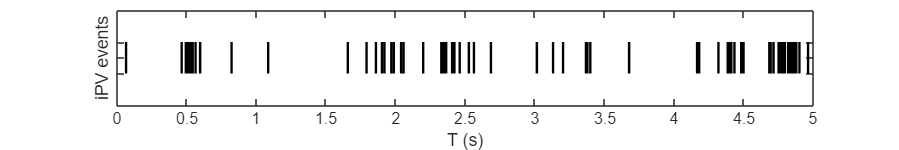


%--------------------------------------------------------------
% | translate iPV activities to presynaptic output current |
%
% raster plot representing the presynaptic events
[~, locs_PV] = findpeaks(v_PV, t_model, "MinPeakHeight",-15);

f_ipv_event = figure('Position', fpos);
plot( [locs_PV; locs_PV]/1000,...
      [zeros(1,length(locs_PV)); ones(1,length(locs_PV))],'LineWidth',1.2,"Color",'k'); 
xlabel('T (s)'); ylabel('iPV events'); yticklabels(''); ylim([-1,2]); xlim([0,TSyn])

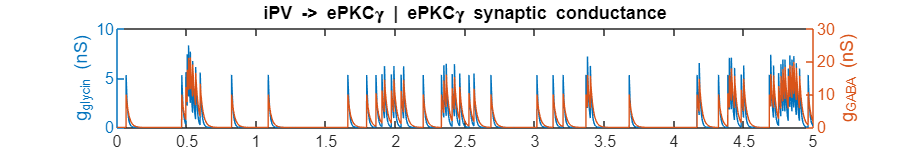

% -- Output to ePKCgamma
tdelay = ( locs_PV )/1000;
w_gaba_pv_pkc = 10; w_glycin_pv_pkc = 5.32; 
gGABA_pv_pkc = genSyn(tStim, tdelay, w_gaba_pv_pkc, rtau_gaba, dtau_gaba);
gGlycin_pv_pkc = genSyn(tStim, tdelay, w_glycin_pv_pkc, rtau_glycin, dtau_glycin);

f_ipv_pkc_syn = figure('Position', fpos);
yyaxis left;  plot(tStim, gGlycin_pv_pkc); ylabel('g_{glycin} (nS)')
yyaxis right; plot(tStim, gGABA_pv_pkc); ylabel('g_{GABA} (nS)')
xlim([0,TSyn]); title('iPV -> ePKC\gamma | ePKC\gamma synaptic conductance');

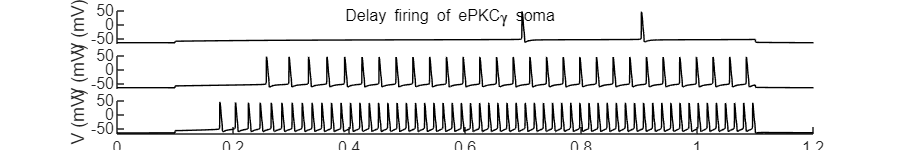

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ePKCgamma: soma delayed firing
% adopted from Figure 1B-delayed in https://www.jneurosci.org/content/jneuro/42/15/3133.full.pdf
% -----------------------------
% Parameter
% -----------------------------
y0 = [-65.3800393278546	0.0224997395328988	0.538717732209865	0.000506922236506564	0.999699095680448	0.00245272612100763	0.0173530730287558	0.436870380291715	0.0800053825919421	0.994718102285383]; % 
% fpos = [0,0,600,500];
figure('Position', fpos);
Iapplist = [200, 150, 125];
for jj = 1:length(Iapplist)
    Iapp = [0, Iapplist(jj), 0]; tstim = [100, 1000, 100]; tstart = 0;
    hAxis = subplot(3,1,4-jj); 
    for ii = 1:3
        sol = ode23tb(@(t,y)ePKCmodel(t,y,Iapp(ii),'step'), 0:dt:tstim(ii), y0 );
        y0=sol.y(:,end);
        plot( (sol.x + tstart)/1000, sol.y(1,:), 'k-'); hold on
        tstart = tstart + tstim(ii);
        xlabel('T (s)'); ylabel('V (mV)'); xlim([0, sum(tstim)/1000]); ylim([-70, 50]); box off
    end
    
    if jj~=1, hAxis.XAxis.Visible = 'off'; end
end
sgtitle('Delay firing of ePKC\gamma soma','FontSize',8);

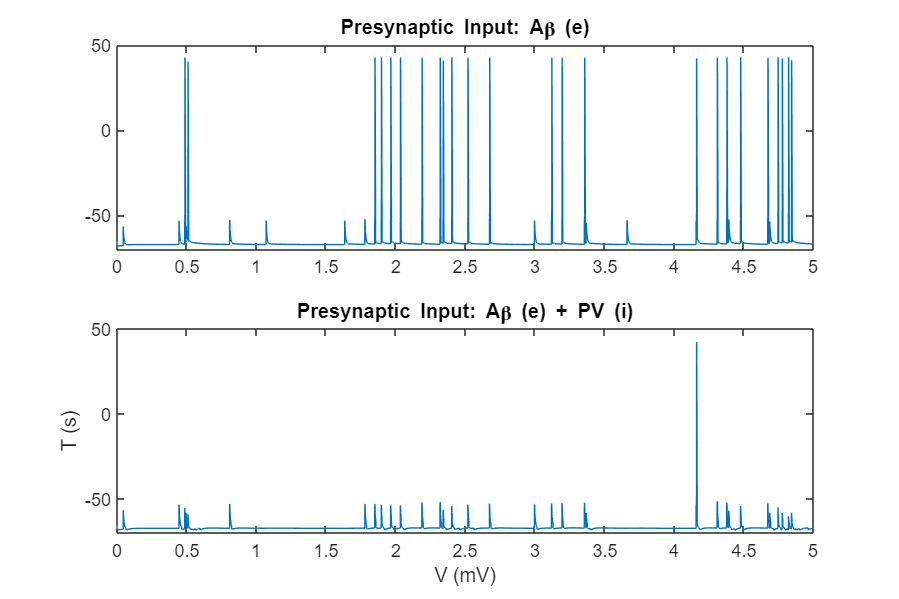

gAMPA = gAMPA_ab_pkc; 
gNMDA = gNMDA_ab_pkc;
y0 = [-65.3800393278546	0.0224997395328988	0.538717732209865	0.000506922236506564	0.999699095680448	0.00245272612100763	0.0173530730287558	0.436870380291715	0.0800053825919421	0.994718102285383]; % 
figure('Position', [0,0,600,400]);
for ii = 1:2
    switch ii
        case 1
            gGABA = zeros(size(gGABA_pv_pkc));
            gGlycin = zeros(size(gGlycin_pv_pkc));
            tname = 'Presynaptic Input: A\beta (e)';
        case 2
            gGABA = gGABA_pv_pkc;
            gGlycin = gGlycin_pv_pkc;
            tname = 'Presynaptic Input: A\beta (e) + PV (i)';
    end
    sol = ode23tb(@(t,y)ePKCmodel(t,y,r,'syn'), 0:dt:5000, y0); 
    subplot(2,1,ii)
    plot(sol.x/1000, sol.y(1,:)); ylim([-70,50]); hold on;
    title(tname)
end
% lgd = legend({'A\beta (e)','A\beta (e) + PV (i)'},'Location',"eastoutside"); title(lgd,'Presynaptic Input');
ylim([-70,50]); xlabel('V (mV)'); ylabel('T (s)')

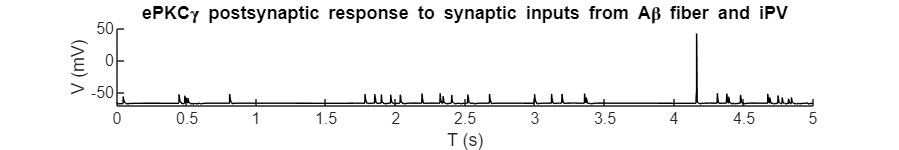

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% ePKCgamma response to Abeta fiber + iPV
% -----------------------------
% Parameter
% -----------------------------
global gAMPA gNMDA gGABA gGlycin tStim
gAMPA = gAMPA_ab_pkc; 
gNMDA = gNMDA_ab_pkc;
gGABA = gGABA_pv_pkc;
gGlycin = gGlycin_pv_pkc;

Iapp = 200; r = [Iapp];
y0 = [-65.3800393278546	0.0224997395328988	0.538717732209865	0.000506922236506564	0.999699095680448	0.00245272612100763	0.0173530730287558	0.436870380291715	0.0800053825919421	0.994718102285383]; %   
v_PKC = []; gSyn = []; rtest = r(end);

% - I=0
trest1 = 0; 

% - test stimuli
r(end) = rtest; ttest = TSyn*1000;
opts = odeset('RelTol',1e-3);
sol = ode23tb(@(t,y)ePKCmodel(t,y,r,'syn'), 0:dt:ttest, y0, opts);
y0 = sol.y(:,end);
v_PKC = [v_PKC(1:end), interp1(sol.x, sol.y(1,:), 0:dt:ttest)];

% - I=0
r(end) = 0; trest2 = 0;

t_model = 0:dt:(trest1+trest2+ttest);

f_pkc_v = figure('Position', fpos);
plot(t_model/1000, v_PKC, 'Color', 'k'); box off; ylim([-70,50]);
xlabel('T (s)'); ylabel('V (mV)'); 
title('ePKC\gamma postsynaptic response to synaptic inputs from A\beta fiber and iPV')